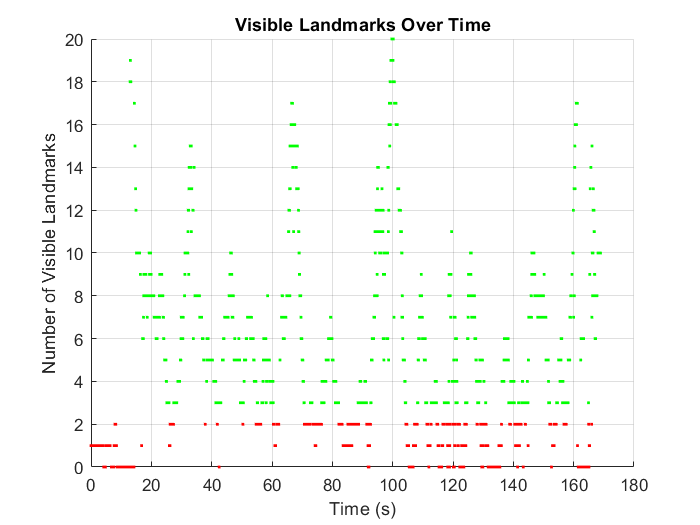

% Load the dataset
load('dataset3.mat');

% Number of timesteps and landmarks
K = size(t, 2); % Number of time steps
M = size(rho_i_pj_i, 2); % Number of landmarks

% Preallocate visibility array
visible_landmarks = zeros(1, K);

% Compute visible landmarks at each timestep
for k = 1:K
    for j = 1:M
        % Check if any component of y_k_j(:,k,j) is valid (not equal to -1)
        if any(y_k_j(:, k, j) ~= -1)
            visible_landmarks(k) = visible_landmarks(k) + 1;
        end
    end
end

% Plot visibility
figure;
hold on;
for k = 1:K
    if visible_landmarks(k) >= 3
        plot(t(k), visible_landmarks(k), 'g.', 'MarkerSize', 5); % Green for 3 or more landmarks
    else
        plot(t(k), visible_landmarks(k), 'r.', 'MarkerSize', 5); % Red otherwise
    end
end
xlabel('Time (s)');
ylabel('Number of Visible Landmarks');
title('Visible Landmarks Over Time');
grid on;
hold off;

% calculate the errors
% use ev,k(xop) = ln(Ξk*Top,k−1*inv(Top,k))underhat
% x=ln(var)underhat just means exp(x^) = var, ie its the inverse operation
% Ξk = exp(w_(k-1)*Tk)
% Fk−1 = inv(J(−ev,k(xop))) * Ad(Top,k*inv(Top,k-1))
% Ek = inv(J(−ev,k(xop))
% then find ey,jk(x) = ey,jk(xop) − Gjk*Zjk*eps_k
% where Gjk = delg/delp at p_jk(xop) [fu/2, 0, -fu*x/z^2; 0, fv/z, -fv*y/z^2; fu/2, 0, -fu(x-b)/z^2; 0, fv/2, -fv*y/z^2]
% Zjk = [-C_cv*C_k,op C_cv*C_k,op*(p_j - r_k,op)_circ]*eps_k
% Then ey,k(x) ≈ ey,k(xop) − Gk*eps_k
% where Gk = [G_1k*Z_1k, ... G_Mk*Z_Mk]
% ey,k(x) = [ey,1k(x); ... ey,Mk(x)]
% ey,k(x_op) = [ey,1k(x_op); ... ey,Mk(x_op)]
% and circ is defined as swap of ^. ie a_circ * b = b^ * a
% the gradient Gjk is evaluated at p_jk(x_op) = C_cv*C_k,op*(p_j − r_k,op) − ρc
% note matlab variables on right side: C_cv = C_c_v, p_j = rho_i_pj_i(:, j), ρc = rho_v_c_v

% Then set up Gauss-Newton solver
% H = two big matrices stacked on top of each other = [H1; H2]
% H1 has E_k1, ... E_k2 along main diag and -F_k1, ... -F_k2 in diagonal
% above main one
% H2 is block diag with diag elements being G_k1 ... G_k2
% e(x_op) = two vectors stacked on top of each other = [e_v(x_op); e_y(x_op)]
% e_v(x_op) = [e_v,k1(x_op) ; ... ; e_v,k2(x_op)]
% e_y(x_op) = [e_y,k1(x_op) ; ... ; e_y,k2(x_op)]
% delx = [eps_k1; ...; eps_k2] is what we are to find. each eps_k? is 6x1
% with first 3 for translation and last 3 for rotation
% W = diag(Q_k1, ..., Q_k2, R_k1, ... R_k2)
% all the Qks are 6x6 diagonal. first 3 diag elements given by elements of Tk*v_var and
% last 3 by Tk*w_var where v_var, w_var are matlab knowns. 
% all the Rkjs are just 3x3 diag with elements Tk*y_var. If time k has M
% landmakrs visisble I guess Rk would be M*3 by M*3 diagonal.

% finally gauss newton solution is to solve the equation below
% A*delx = b
% where A = H'*inv(W)*H, b = H'*inv(W)*e(x_op)
% A is block tridiagonal
% this gives up the optimal perturbation which allows us to update Top
% Top,k = exp(eps^_k)*Top,k
% then repeat process

% Parameters for the problem
k1 = 1215;
k2 = 1714;

% Load necessary data (e.g., t, r_i_vk_i, etc.)
% Assume the data is loaded here as variables t, r_i_vk_i, theta_vk_i, ...
% v_vk_vk_i, w_vk_vk_i, y_k_j, rho_i_pj_i, C_c_v, rho_v_c_v, fu, fv, b,
% v_var, w_var, y_var.

% Call Gauss-Newton algorithm
[Top_final, converged] = gauss_newton_se3(k1, k2, t, r_i_vk_i, theta_vk_i, ...
    v_vk_vk_i, w_vk_vk_i, y_k_j, rho_i_pj_i, C_c_v, rho_v_c_v, fu, fv, b, cu, cv, ...
    v_var, w_var, y_var);

     0



     1



     2



     3



     4



     5



     6



     7



     8



function [Top_final, converged] = gauss_newton_se3(k1, k2, t, r_i_vk_i, theta_vk_i, v_vk_vk_i, w_vk_vk_i, y_k_j, rho_i_pj_i, C_c_v, rho_v_c_v, fu, fv, b, cu, cv, v_var, w_var, y_var)
    % Function to perform Gauss-Newton optimization for SE(3) transformations.
    % Inputs:
    %   k1, k2: Start and end indices for the time window
    %   t: Time vector
    %   r_i_vk_i: Translation vectors
    %   theta_vk_i: Rotation vectors
    %   v_vk_vk_i: Linear velocities
    %   w_vk_vk_i: Angular velocities
    %   y_k_j: Landmark observations
    %   rho_i_pj_i: Landmark positions
    %   C_c_v: Camera intrinsic matrix
    %   rho_v_c_v: Camera offset vector
    %   fu, fv, b: Camera parameters
    %   v_var, w_var, y_var: Covariances for motion and observation models
    % Outputs:
    %   Top_final: Final state estimate (4x4xK)
    %   converged: Boolean indicating whether convergence was achieved

    % Initialize Top using the ground truth at k1
    K_window = k2 - k1 + 1; % Define the size of the window
    Top = zeros(4, 4, K_window); % Preallocate space for Top within the window
    r_k1 = r_i_vk_i(:, k1);
    theta_k1 = theta_vk_i(:, k1);
    R_k1 = expm(skew(theta_k1));
    Top(:, :, 1) = [R_k1, r_k1; 0, 0, 0, 1];

    % Dead-reckon to initialize Top for subsequent timesteps
    for k = 2:K_window
        k_curr = k1 + k - 1;
        Tk = t(k_curr) - t(k_curr - 1);
        v_vk_vk = v_vk_vk_i(:, k_curr - 1);
        w_vk_vk = w_vk_vk_i(:, k_curr - 1);
        r_prev = Top(1:3, 4, k - 1);
        R_prev = Top(1:3, 1:3, k - 1);

        % Update rotation
        theta_delta = w_vk_vk * Tk;
        R_curr = expm(skew(theta_delta)) * R_prev;

        % Update translation
        r_delta = R_prev' * (v_vk_vk * Tk);
        r_curr = r_prev + r_delta;

        % Update Top
        Top(:, :, k) = [R_curr, r_curr; 0, 0, 0, 1];
    end
    
    % Gauss-Newton loop
    converged = false;
    iteration = 0;
    max_iterations = 200;
    epsilon_threshold = 1e-6;

    while ~converged && iteration < max_iterations
        disp(iteration)
        
        % Initialize variables for this iteration
        H1 = zeros(6 * K_window, 6 * K_window);
        H2_blocks = {};
        Q_blocks = {};
        R_blocks = {};
        e_v = [];
        e_y = [];

        % Compute e_{v,0}(x_{op})
        Top_k = Top(:, :, 1);
        % Use ground truth from r_i_vk_i and theta_vk_i for T_gt_0
        r_gt_0 = r_i_vk_i(:, k1); % Ground truth translation
        theta_gt_0 = theta_vk_i(:, k1); % Ground truth rotation
        R_gt_0 = expm(skew(theta_gt_0)); % Compute rotation matrix from theta
        T_gt_0 = [R_gt_0, r_gt_0; 0, 0, 0, 1]; % Ground truth transformation matrix        ev_0_matrix = logm(T_gt_0 * T_op_0_inv);
        ev_0_matrix = logm(T_gt_0 / T_op_k);
        ev_0 = [vee(ev_0_matrix(1:3, 1:3)); ev_0_matrix(1:3, 4)];
        E_k1 = inv(SE3_jacobian(-ev_0));
        e_v = [e_v; ev_0];
        H1(1:6, 1:6) = E_k1;
        dummy = t(1,2) - t(1,1);
        Q_k1 = diag([dummy^2 * v_var; dummy^2 * w_var]);
        Q_blocks{end + 1} = Q_k1;

        % Include ey,0 and the first R covariance matrix
        visible_landmarks_k1 = find(any(y_k_j(:, k1, :) ~= -1, 1));
        Gk1 = [];
        ey_k1 = [];
        
        if isempty(visible_landmarks_k1)
            % If no measurements exist, append zeros
            Gk1 = zeros(0, 6); % No observation Jacobians
            ey_k1 = zeros(0, 1); % No observation errors
        else
            for idx = 1:numel(visible_landmarks_k1)
                j = visible_landmarks_k1(idx); % Extract the current element
                C_k = Top(1:3, 1:3, 1);
                r_k = Top(1:3, 4, 1);
                p_j = rho_i_pj_i(:, j);
                p_jk_xop = C_c_v * C_k * (p_j - r_k) - rho_v_c_v;
    
                % Extract x, y, z from p_jk_xop
                x = p_jk_xop(1);
                y = p_jk_xop(2);
                z = p_jk_xop(3);
                
                % Apply g function to compute predicted observation
                g_p_jk_xop = g_function(x, y, z, fu, fv, b, cu, cv);
                
                % Observation error
                ey_jk = y_k_j(:, k1, j) - g_p_jk_xop;
    
                % Compute Gjk
                x = p_jk_xop(1); y = p_jk_xop(2); z = p_jk_xop(3);
                G_jk = [fu / 2, 0, -fu * x / z^2;
                        0, fv / z, -fv * y / z^2;
                        fu / 2, 0, -fu * (x - b) / z^2;
                        0, fv / 2, -fv * y / z^2];
                Z_jk = [-C_c_v * C_k, -C_c_v * C_k * skew(p_j - r_k)];
                Gk1 = [Gk1; G_jk * Z_jk];
                ey_k1 = [ey_k1; ey_jk];
            end
        end
        H2_blocks{end + 1} = Gk1;
        e_y = [e_y; ey_k1];
        % Create R_k1 with M blocks, each block being diag(y_var)
        M = numel(visible_landmarks_k1); % Number of visible landmarks
        diag_blocks = repmat({diag(y_var)}, 1, M); % Cell array of diag(y_var)
        R_k1 = blkdiag(diag_blocks{:}); % Construct block diagonal matrix
        R_blocks{end + 1} = R_k1;

        % Loop through timesteps for k = 2 to K_window
        for k = 2:K_window
            k_curr = k1 + k - 1;

            % Compute Ξk = exp(w_(k-1) * Tk)
            Tk = t(k_curr) - t(k_curr - 1);
            psi_k = w_vk_vk_i(:, k_curr - 1) * Tk;
            rho_k = v_vk_vk_i(:, k_curr - 1) * Tk; % Linear velocity * time
            
            % Construct the SE(3) matrix Ξk
            Xi_k = expm([skew(psi_k), rho_k; 0, 0, 0, 0]); % SE(3) exponential map

            % Compute motion model error ev,k(xop)
            Top_k = Top(:, :, k);
            Top_km1 = Top(:, :, k - 1);
            ev_k = logm(Xi_k * Top_km1 / Top_k); % Lie logarithm
            ev_hat = vee(ev_k(1:3, 1:3)); % Rotation vector
            ev_trans = ev_k(1:3, 4); % Translation error
            e_v = [e_v; ev_hat; ev_trans]; % Append motion model errors

            % Compute Jacobians Fk and Ek for the motion model
            F_k = inv(SE3_jacobian(-[ev_trans; ev_hat])) * SE3_adjoint(Top_k * inv(Top_km1));
            E_k = inv(SE3_jacobian(-[ev_trans; ev_hat]));

            % Place E_k and -F_k into H1
            H1((k - 1) * 6 + 1:k * 6, (k - 1) * 6 + 1:k * 6) = E_k; % Main diagonal
            H1((k - 1) * 6 + 1:k * 6, (k - 2) * 6 + 1:(k - 1) * 6) = -F_k; % Subdiagonal

            % Observation model Jacobians
            visible_landmarks_k = find(any(y_k_j(:, k_curr, :) ~= -1, 1)); % Get visible landmarks
            Gk = [];
            ey_k = [];
                        
            if isempty(visible_landmarks_k)
                % If no measurements exist, append zeros
                Gk = zeros(0, 6); % No observation Jacobians
                ey_k = zeros(0, 1); % No observation errors
                R_k = zeros(0, 0); % No observation covariance
            else
                Gk = []; % Reset Gk for this timestep
                ey_k = []; % Reset ey_k for this timestep
                for idx = 1:numel(visible_landmarks_k)
                    j = visible_landmarks_k(idx); % Extract the current element
                    % Compute observation model error ey,jk(xop)
                    C_k = Top(1:3, 1:3, k);
                    r_k = Top(1:3, 4, k);
                    p_j = rho_i_pj_i(:, j);
                    p_jk_xop = C_c_v * C_k * (p_j - r_k) - rho_v_c_v;
            
                    % Extract x, y, z from p_jk_xop
                    x = p_jk_xop(1);
                    y = p_jk_xop(2);
                    z = p_jk_xop(3);
            
                    % Apply g function to compute predicted observation
                    g_p_jk_xop = g_function(x, y, z, fu, fv, b, rho_v_c_v(1), rho_v_c_v(2));
            
                    % Observation error
                    ey_jk = y_k_j(:, k_curr, j) - g_p_jk_xop;
            
                    % Compute Gjk
                    G_jk = [fu / 2, 0, -fu * x / z^2;
                            0, fv / z, -fv * y / z^2;
                            fu / 2, 0, -fu * (x - b) / z^2;
                            0, fv / 2, -fv * y / z^2];
            
                    % Compute Zjk
                    Z_jk = [-C_c_v * C_k, -C_c_v * C_k * skew(p_j - r_k)];
                    Gk = [Gk; G_jk * Z_jk];
                    ey_k = [ey_k; ey_jk];
                end
            
                % Create R_k with M blocks, each block being diag(y_var)
                M = numel(visible_landmarks_k); % Number of visible landmarks
                diag_blocks = repmat({diag(y_var)}, 1, M); % Cell array of diag(y_var)
%                 disp('size of diagblock')
%                 disp(size(diag_blocks))
                R_k = blkdiag(diag_blocks{:}); % Construct block diagonal matrix
%                 disp('size of R_k')
%                 disp(size(R_k))
%                 disp('size of Gk')
%                 disp(size(Gk))
            end
            
            % Add Gk and ey_k to H2_blocks and e_y
            H2_blocks{end + 1} = Gk;
            e_y = [e_y; ey_k]; % Append observation model errors
            
            % Add R_k to R_blocks
            R_blocks{end + 1} = R_k;
            
            % Add Q_k to Q_blocks
            Q_k = diag([Tk^2 * v_var; Tk^2 * w_var]); % Motion model covariance
            Q_blocks{end + 1} = Q_k;
        
        end
        
        % Combine motion and observation model errors
        e_x_op = [e_v; e_y];

        % Combine H2_blocks into a block diagonal matrix
        H2 = blkdiag(H2_blocks{:});

        % Combine Q and R blocks
%         disp(size(Q_blocks));
%         disp(size(R_blocks));
%         disp(size(blkdiag(Q_blocks{:})));
%         disp(size(blkdiag(R_blocks{:})));
        W = blkdiag(blkdiag(Q_blocks{:}), blkdiag(R_blocks{:}));

        % Combine H1 and H2
%         disp(size(H1))
%         disp(size(H2))
        H = [H1; H2];
        A = H' * (W \ H);
        bans = H' * (W \ e_x_op);

        % Solve for delta x
        delx = A \ bans;

        % Update Top,k
        for k = 1:K_window
            epsilon_k = delx((k - 1) * 6 + 1:k * 6);
            rho = epsilon_k(1:3);
            phi = epsilon_k(4:6);
            perturbation = expm([skew(phi), rho; zeros(1, 4)]);
            Top(:, :, k) = perturbation * Top(:, :, k);
        end

        % Check for convergence
        if norm(delx) < epsilon_threshold
            converged = true;
        else
            iteration = iteration + 1;
        end
    end

    Top_final = Top;
end

function S = skew(v)
    % Converts vector v into a skew-symmetric matrix
    S = [0, -v(3), v(2); v(3), 0, -v(1); -v(2), v(1), 0];
end

% Supporting function for skew-symmetric matrix
function v = vee(S)
    % Converts skew-symmetric matrix to vector
    v = [S(3, 2); S(1, 3); S(2, 1)];
end

function J = SO3_jacobian(phi)
    % Compute Jacobian for SE(3) exponential map
    norm_phi = norm(phi);
    if norm_phi < 1e-6
        J = eye(3); % Small-angle approximation
        return;
    end
    a = phi / norm_phi; % Unit vector
    phi_hat = skew(a); % Skew-symmetric form of a
    J = sin(norm_phi) / norm_phi * eye(3) + ...
        (1 - sin(norm_phi) / norm_phi) * (a * a') + ...
        (1 - cos(norm_phi)) / norm_phi * phi_hat;
end

function J_inv = SO3_jacobian_inverse(phi)
    % Compute the inverse Jacobian for SO(3)
    % Inputs:
    %   phi: 3x1 vector (axis-angle representation)
    % Outputs:
    %   J_inv: 3x3 inverse Jacobian matrix
    
    norm_phi = norm(phi); % Magnitude of the rotation vector
    
    if norm_phi < 1e-6
        % Small-angle approximation
        J_inv = eye(3) - 0.5 * skew(phi); 
        return;
    end
    
    % Unit vector along the rotation axis
    a = phi / norm_phi; 
    
    % Precompute terms for efficiency
    cot_term = (norm_phi / 2) * cot(norm_phi / 2);
    a_hat = skew(a); % Skew-symmetric matrix of 'a'
    
    % Compute the inverse Jacobian
    J_inv = (cot_term) * eye(3) + ...
            (1 - cot_term) * (a * a') - ...
            (norm_phi / 2) * a_hat;
end

function AdT = SE3_adjoint(T)
    % Compute the adjoint matrix for a transformation T in SE(3)
    C = T(1:3, 1:3); % Rotation matrix
    r = T(1:3, 4); % Translation vector
    AdT = [C, skew(r) * C; zeros(3), C];
end

function J = SE3_jacobian(rho_phi)
    % Compute the Jacobian for SE(3) exponential map
    % Inputs:
    %   rho_phi: 6x1 vector [rho; phi], where
    %            rho is the translation vector (3x1)
    %            phi is the rotation vector (3x1)
    % Outputs:
    %   J: 6x6 Jacobian matrix for SE(3)

    % Split input into rho and phi
    rho = rho_phi(1:3); % Translation part
    phi = rho_phi(4:6); % Rotation part
    norm_phi = norm(phi); % Norm of the rotation vector
    
    % Compute the SO(3) Jacobian (J_SO3) for the rotation part
    J_SO3 = SO3_jacobian(phi); 
    
    % Compute the Q matrix for the translation part
    if norm_phi < 1e-6
        % Small-angle approximation
        Q = 0.5 * skew(rho);
    else
        phi_hat = skew(phi); % Skew-symmetric matrix of phi
        rho_hat = skew(rho); % Skew-symmetric matrix of rho
        Q = 0.5 * rho_hat + ...
            (norm_phi - sin(norm_phi)) / norm_phi^3 * (phi_hat*rho_hat + rho_hat*phi_hat + phi_hat*rho_hat*phi_hat) - ...
            (1 - norm_phi^2 / 2 - cos(norm_phi)) / norm_phi^4 * (phi_hat*phi_hat*rho_hat + rho_hat*phi_hat*phi_hat - 3*phi_hat*rho_hat*phi_hat) - ...
            0.5 * ((1 - norm_phi^2/2 - cos(norm_phi))/norm_phi^4 - 3*(norm_phi - sin(norm_phi) - norm_phi^3/6)/norm_phi^5) * (phi_hat*rho_hat*phi_hat*phi_hat + phi_hat*phi_hat*rho_hat*phi_hat);
    end
    
    % Assemble the SE(3) Jacobian matrix
    J = [J_SO3, Q; zeros(3), J_SO3];
end

function J_inv = SE3_jacobian_inverse(rho_phi)
    % Compute the inverse Jacobian for SE(3)
    % Inputs:
    %   rho_phi: 6x1 vector [rho; phi], where
    %            rho is the translation vector (3x1)
    %            phi is the rotation vector (3x1)
    % Outputs:
    %   J_inv: 6x6 inverse Jacobian matrix for SE(3)

    % Split input into rho and phi
    rho = rho_phi(1:3); % Translation part
    phi = rho_phi(4:6); % Rotation part
    norm_phi = norm(phi); % Norm of the rotation vector
    
    % Compute the inverse SO(3) Jacobian (J_SO3_inv) for the rotation part
    J_SO3_inv = SO3_jacobian_inverse(phi); 
    
    % Compute the Q matrix for the translation part
    if norm_phi < 1e-6
        % Small-angle approximation
        Q = 0.5 * skew(rho);
    else
        phi_hat = skew(phi); % Skew-symmetric matrix of phi
        rho_hat = skew(rho); % Skew-symmetric matrix of rho
        Q = 0.5 * rho_hat + ...
            (norm_phi - sin(norm_phi)) / norm_phi^3 * (phi_hat*rho_hat + rho_hat*phi_hat + phi_hat*rho_hat*phi_hat) - ...
            (1 - norm_phi^2 / 2 - cos(norm_phi)) / norm_phi^4 * (phi_hat*phi_hat*rho_hat + rho_hat*phi_hat*phi_hat - 3*phi_hat*rho_hat*phi_hat) - ...
            0.5 * ((1 - norm_phi^2/2 - cos(norm_phi))/norm_phi^4 - 3*(norm_phi - sin(norm_phi) - norm_phi^3/6)/norm_phi^5) * (phi_hat*rho_hat*phi_hat*phi_hat + phi_hat*phi_hat*rho_hat*phi_hat);
    end
    
    % Assemble the SE(3) inverse Jacobian matrix
    J_inv = [J_SO3_inv, -J_SO3_inv * Q * J_SO3_inv; ...
             zeros(3), J_SO3_inv];
end

% Compute the g function as per the formula
function g_val = g_function(x, y, z, fu, fv, b, cu, cv)
    % Compute the intrinsic camera parameters
    g_val = (1 / z) * [fu * x + cu;
                       fv * y + cv;
                       fu * (x - b) + cu;
                       fv * y + cv];
end

